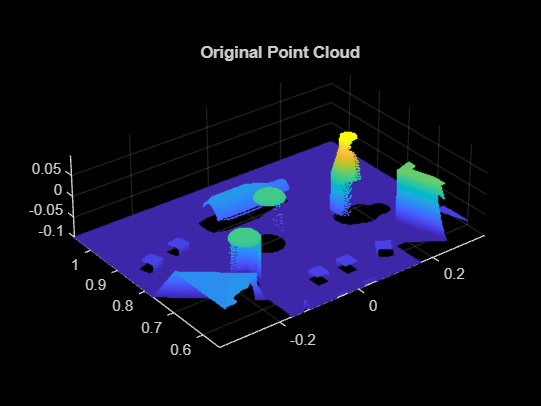

% Define the path to the point cloud file
filePath = 'C:\Users\moham\Desktop\phase_4_pc.ply';

% Read the point cloud from the PLY file
ptCloud = pcread(filePath);

% Extract the points from the point cloud
points = ptCloud.Location;

% Display the original point cloud
figure;
pcshow(ptCloud);
title('Original Point Cloud');

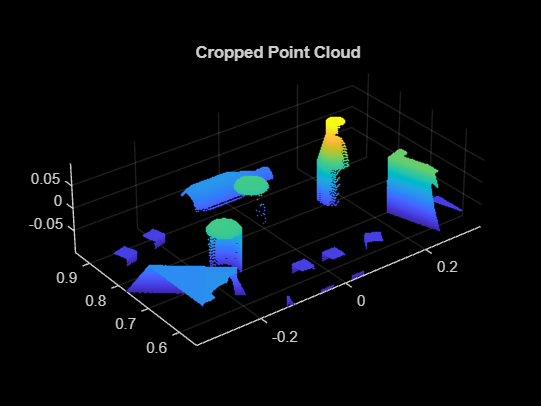


% Define the range for cropping along the Z-axis
zMin = -0.099;  % Minimum Z value
zMax = 0.2;    % Maximum Z value

% Filter the points based on the Z-axis range
filteredPoints = points(points(:,3) >= zMin & points(:,3) <= zMax, :);

% Create a new point cloud with the filtered points
croppedPtCloud = pointCloud(filteredPoints);

% Optionally, save the cropped point cloud to a new PLY file
outputFilePath = 'C:\Users\moham\Desktop\cropped_phase_4_pc.ply';
pcwrite(croppedPtCloud, outputFilePath);

% Display the cropped point cloud
figure;
pcshow(croppedPtCloud);
title('Cropped Point Cloud');

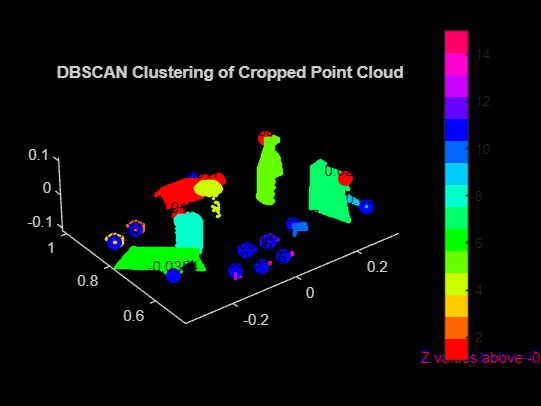


% Assuming filteredPoints contains the cropped point cloud data
% Define DBSCAN parameters
eps = 0.035;     % Maximum distance for two points to be considered neighbors
min_points = 10; % Minimum number of points to form a dense region (cluster)

% Perform DBSCAN clustering on the cropped point cloud
clusters = dbscan(filteredPoints, eps, min_points);

% Determine the number of clusters formed (excluding noise points)
numClusters = max(clusters);

% Find the highest Z value in each cluster
highestZValues = zeros(numClusters, 1);
highestPoints = zeros(numClusters, 3);

for i = 1:numClusters
    % Extract points belonging to the current cluster
    clusterPoints = filteredPoints(clusters == i, :);
    
    % Find the highest point in the current cluster (maximum Z value)
    [~, idx] = max(clusterPoints(:, 3));
    highestPoints(i, :) = clusterPoints(idx, :);
    
    % Store the highest Z value
    highestZValues(i) = highestPoints(i, 3);
end

% Display the highest Z values alongside the clustered point cloud
figure;
hold on;

% Plot all points with clusters colored according to DBSCAN clustering
pcshow(filteredPoints, clusters, 'MarkerSize', 50);
colormap(hsv(numClusters));
colorbar;
title('DBSCAN Clustering of Cropped Point Cloud');

% Highlight clusters below threshold in blue
clusters_below = find(highestZValues < -0.00765);
scatter3(highestPoints(clusters_below, 1), highestPoints(clusters_below, 2), highestPoints(clusters_below, 3), ...
    100, 'b', 'filled');

% Highlight clusters above threshold in red
clusters_above = find(highestZValues > -0.00675);
scatter3(highestPoints(clusters_above, 1), highestPoints(clusters_above, 2), highestPoints(clusters_above, 3), ...
    100, 'r', 'filled');

% Annotate highest Z values on the plot
text(highestPoints(:, 1), highestPoints(:, 2), highestPoints(:, 3), ...
    num2str(highestZValues, '%.4f'), 'FontSize', 10, 'Color', 'k', ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'center');

% Display Z values below and above thresholds
text(-0.1, -0.075, ['Z values below -0.00765: ', num2str(highestZValues(clusters_below)', '%.4f')], 'Color', 'b');
text(-0.1, -0.08, ['Z values above -0.00675: ', num2str(highestZValues(clusters_above)', '%.4f')], 'Color', 'r');

hold off;

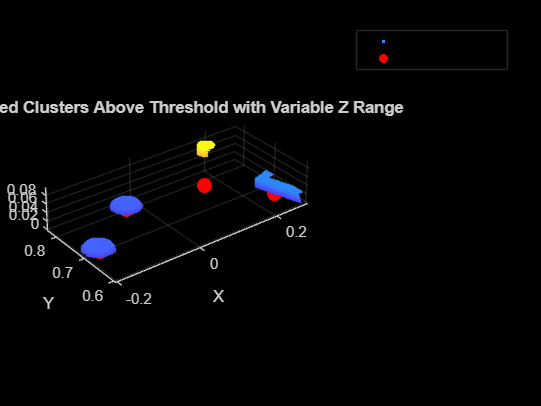



% Define thresholds for cropping clusters above the threshold
zOffset = 0.02;  % Offset from maximum Z value for minimum Z value

% Initialize arrays to store cropped points and cluster centers
croppedPoints = [];
clusterCenters = zeros(length(clusters_above), 2);  % Each row will store (x, y) center coordinates

% Iterate through clusters above the threshold
for k = 1:length(clusters_above)
    i = clusters_above(k);  % Get cluster index
    % Extract points belonging to the current cluster
    clusterPoints = filteredPoints(clusters == i, :);
    
    % Find maximum and minimum Z values of the current cluster
    maxZ = max(clusterPoints(:, 3));
    minZ = maxZ - zOffset;
    
    % Crop points based on the Z-axis range
    croppedClusterPoints = clusterPoints(clusterPoints(:, 3) >= minZ & clusterPoints(:, 3) <= maxZ, :);
    
    % Calculate centroid (center) of the current cluster in x and y dimensions
    clusterCenterX = mean(croppedClusterPoints(:, 1));
    clusterCenterY = mean(croppedClusterPoints(:, 2));
    
    % Store cluster center coordinates
    clusterCenters(k, :) = [clusterCenterX, clusterCenterY];
    
    % Append cropped points to the array (if needed)
    croppedPoints = [croppedPoints; croppedClusterPoints];
end

% Create a point cloud with the cropped points (optional)
croppedClustersAboveThreshold = pointCloud(croppedPoints);

% Display the cropped clusters above threshold within the specified Z range
figure;
pcshow(croppedClustersAboveThreshold);
hold on;
scatter(clusterCenters(:, 1), clusterCenters(:, 2), 100, 'r', 'filled');
hold off;
title('Cropped Clusters Above Threshold with Variable Z Range');
xlabel('X');
ylabel('Y');
legend('Cluster Points', 'Cluster Centers');


% Optionally, save the cropped point cloud to a new PLY file
outputFilePath = 'C:\Users\moham\Desktop\cropped_clusters_above_threshold_varzrange.ply';
pcwrite(croppedClustersAboveThreshold, outputFilePath);

% Display cluster centers with their calculated Z values
disp('Cluster Centers (X, Y):');

Cluster Centers (X, Y):


clusterCentersWithZ = [clusterCenters, maxZ * ones(length(clusters_above), 1)];
disp(clusterCentersWithZ);

   -0.0326    0.7982    0.0172
    0.1578    0.7791    0.0172
    0.2546    0.6631    0.0172
   -0.1682    0.7003    0.0172



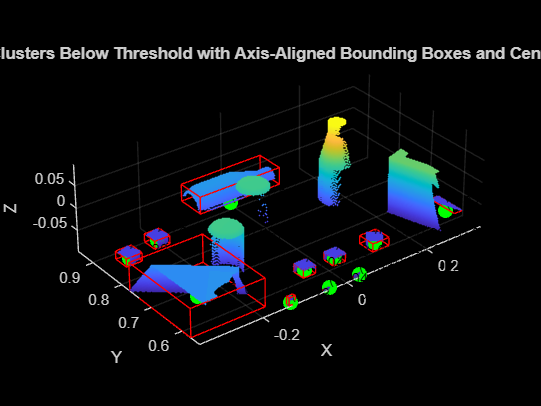



% Find the clusters below the threshold
threshold_below = -0.00765;

% Initialize arrays to store bounding box vertices and cluster centers
bboxVertices = cell(numClusters, 1);
clusterCenters = zeros(numClusters, 2);  % Each row will store (centerX, centerY)

% Iterate through each cluster
for i = 1:numClusters
    % Get the highest Z value of the current cluster
    highestZ = max(filteredPoints(clusters == i, 3));
    
    % Check if cluster is below threshold
    if highestZ < threshold_below
        % Extract points belonging to the current cluster
        clusterPoints = filteredPoints(clusters == i, :);
        
        % Calculate axis-aligned bounding box (AABB)
        minXYZ = min(clusterPoints, [], 1);  % Minimum X, Y, Z values
        maxXYZ = max(clusterPoints, [], 1);  % Maximum X, Y, Z values
        
        % Create vertices of the bounding box
        bboxVertices{i} = [
            minXYZ(1), minXYZ(2), minXYZ(3);
            maxXYZ(1), minXYZ(2), minXYZ(3);
            maxXYZ(1), maxXYZ(2), minXYZ(3);
            minXYZ(1), maxXYZ(2), minXYZ(3);
            minXYZ(1), minXYZ(2), maxXYZ(3);
            maxXYZ(1), minXYZ(2), maxXYZ(3);
            maxXYZ(1), maxXYZ(2), maxXYZ(3);
            minXYZ(1), maxXYZ(2), maxXYZ(3);
        ];
        
        % Calculate center of the bounding box in x and y dimensions
        centerX = (minXYZ(1) + maxXYZ(1)) / 2;
        centerY = (minXYZ(2) + maxXYZ(2)) / 2;
        
        % Store cluster center coordinates
        clusterCenters(i, :) = [centerX, centerY];
    end
end

% Visualize clusters with bounding boxes and centers
figure;
pcshow(filteredPoints);
hold on;
for i = 1:numClusters
    if ~isempty(bboxVertices{i})
        vertices = bboxVertices{i};
        % Plot bounding box
        plot3(vertices([1 2 3 4 1], 1), vertices([1 2 3 4 1], 2), vertices([1 2 3 4 1], 3), 'r-');
        plot3(vertices([5 6 7 8 5], 1), vertices([5 6 7 8 5], 2), vertices([5 6 7 8 5], 3), 'r-');
        plot3([vertices(1,1), vertices(5,1)], [vertices(1,2), vertices(5,2)], [vertices(1,3), vertices(5,3)], 'r-');
        plot3([vertices(2,1), vertices(6,1)], [vertices(2,2), vertices(6,2)], [vertices(2,3), vertices(6,3)], 'r-');
        plot3([vertices(3,1), vertices(7,1)], [vertices(3,2), vertices(7,2)], [vertices(3,3), vertices(7,3)], 'r-');
        plot3([vertices(4,1), vertices(8,1)], [vertices(4,2), vertices(8,2)], [vertices(4,3), vertices(8,3)], 'r-');
        
        % Plot cluster center
        scatter3(clusterCenters(i, 1), clusterCenters(i, 2), highestZ, 100, 'g', 'filled');
        
        % Display cluster center coordinates (x, y, z)
        text(clusterCenters(i, 1), clusterCenters(i, 2), highestZ, ...
            sprintf('(%0.2f, %0.2f, %0.2f)', clusterCenters(i, 1), clusterCenters(i, 2), highestZ), ...
            'FontSize', 10, 'Color', 'k', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'left');
    end
end
hold off;
title('Clusters Below Threshold with Axis-Aligned Bounding Boxes and Centers');
xlabel('X');
ylabel('Y');
zlabel('Z');
grid on;


disp('Cluster Centers (X, Y):');

Cluster Centers (X, Y):


disp([clusterCenters]);

   -0.0005    0.9178
   -0.2041    0.8855
   -0.2842    0.8656
         0         0
         0         0
   -0.2601    0.6720
         0         0
         0         0
    0.3249    0.6298
    0.1304    0.6210
   -0.0423    0.6218
    0.0306    0.6208
   -0.1314    0.5499
    0.0329    0.5486
   -0.0413    0.5476

